# **Элементы программирования**

## Теория

### 3.1.1 Специальные символы

pi; % число пи
ans; % результат выполнения операции
inf; % бесконечность
nan; % нечисловое значение

#### Пример 1

1e309
1 / inf 
inf - inf
inf + nan
1 / nan
1 / 0
-1 / 0
0 / 0

### 3.1.2 Типы данных

help DataTypes

Функции определения типа данных:

% isinf, isfinite, isnan, isnumeric, islogical, ischar, iscell, isstruct,
% isfloat, isinteger, isobject, isjava, issparse, isreal, class, isa

### 3.1.3 Текстовые строки

s3 = 'Hello, Matlab'
disp(s3)
n1 = input('Input the num ')
help strfun

### 3.2 Управление вычислением

#### Пример 2

% Определить знак S рационального числа X

X = 20
% if: оператор условия: вычисляет логическое выражение и выполняет группу операторов, если выражение истинно

if X > 0
    S = 1;
elseif ~X % все ненулевые значения будут нулями, нуль - единицей
    S = 0;
else
    S = -1;
end

S

% Вариант 2 (без оператора if):

X = [4:-2:-4], S = (X > 0) - (X < 0)

#### Пример 3

% switch: оператор переключения: выполняет группу операторов в зависимости от значения переменной или выражения

appl = 'MATLAB';
switch upper(appl)
    case {'MATLAB', 'MATCAD'}
        disp('Application is numeric')
    case {'MAPLE', 'MATHEMATICA'}
        disp('Application is symbolic')
    otherwise
        disp('Unknown application')
end

#### Пример 4

n = 7;
switch n
 case {1, 4, 9}, fprintf('%d – Quadrate\n', n);
 case {2, 3, 5, 7}, fprintf('%d – Prima\n', n);
 case 6, fprintf('%d – factorial 3!\n', n);
 case 8, fprintf('%d – Cubic\n', n);
 otherwise
 disp('n must be natural number from 1 to 9.');
end

% Вычислить сумму отрезка ряда с заданной точностью

S = 0; n = 1; x = 1;
while x > 1e-10
    S = S + x;
    n = n + 1; x = 1 / factorial(n);
end
[x, n]
% while: оператор цикла: повторяет группу операторов до тех пор, пока выполняется логическое условие;
% for: оператор цикла: выполняет группу операторов заданное число раз;
% break: оператор управления: выполняет досрочный выход из циклов for или while;
% continue: оператор управления: передает управление следующей итерации циклов for или while. 

## Задания

### Задание 1

Чему равно наибольшее число, для которого можно вычислить факториал в пакете MATLAB?

n = 1;
while ~isinf(factorial(n))
    n = n + 1;
end

disp(n)
fprintf('%d! = %d, %d! = %d', n - 1, factorial(n - 1), n, factorial(n));

% другой вариант

n = 1;
while true
    if factorial(n) == inf
        n = n - 1;
        break;
    else
        n = n + 1;
    end
end

disp(n)

### Задание 2

Организуйте цикл, в котором вводите с клавиатуры название дня недели, и при помощи оператора switch определите номер дня недели по названию дня недели. Выход из цикла – по вводу текстовой строки «exit». Обработайте некорректный ввод названия дня недели.

exit = false
while ~exit
    day = input('Enter the day of the week: ', 's')
    switch upper(day)
    case 'MONDAY'
        day_n = 1;
    case 'TUESDAY'
        day_n = 2;
    case 'WEDNESDAY'
        day_n = 3;
    case 'THURSDAY'
        day_n = 4;
    case 'FRIDAY'
        day_n = 5;
    case 'SATURDAY'
        day_n = 6;
    case 'SUNDAY'
        day_n = 7;
    case 'EXIT'
        exit = true;
    otherwise
        day_n = 0;
    end
    if exit
        disp('The exit.')
    elseif ~day_n
        disp('Incorrect input. Try again.')
    else
        disp(['The num of the ', day, ' is ', int2str(day_n), '.'])
    end
end

### Задание 3

Организуйте цикл, в котором вводите с клавиатуры номер месяца, и при помощи оператора switch определите название месяца по его номеру. Обработайте некорректный ввод номера дня недели. Выход из цикла – по вводу числа 0.

exit = false
while ~exit
    month_n = input('Enter the month of the year: ', 's')
    switch month_n
    case '1'
        month = 'January';
    case '2'
        month = 'February';
    case '3'
        month = 'March';
    case '4'
        month = 'April';
    case '5'
        month = 'May';
    case '6'
        month = 'June';
    case '7'
        month = 'July';
    case '8'
        month = 'August';
    case '9'
        month = 'September';
    case '10'
        month = 'October';
    case '11'
        month = 'November';
    case '12'
        month = 'December';
    case '0'
        exit = true;
    otherwise
        month = 0;
    end
    if exit
        disp('The exit.')
    elseif ~month
        disp('Incorrect input. Try again.')
    else
        disp(['The ', month_n, ' month of the year is ', month, '.'])
    end
end

### Задание 4

Функция input. Введите и выполните команды.

M = input('Input (nx2)-Matrix: ')

### Задание 5

Функция input и disp. Введите и выполните команды.

A = input('Input the Number : A = ')

disp(['The number A is: ', int2str(A)])

S = input('Input the string : S = ', 's')

### Задание 6

3D-графика. Введите команды.

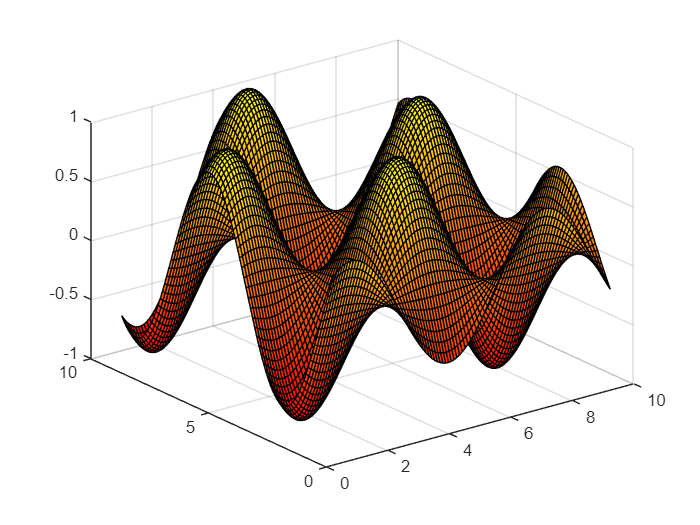

a = linspace(1, 10, 100);
[x y] = meshgrid(a); % возвращает 2D сетку координат, основанную на координатах, содержащихся в векторе a, x - матрица, где каждая строка копия a y - это матрица,
% где каждый столбец - копия a
z = sin(x) .* cos(y);
surf(x, y, z)

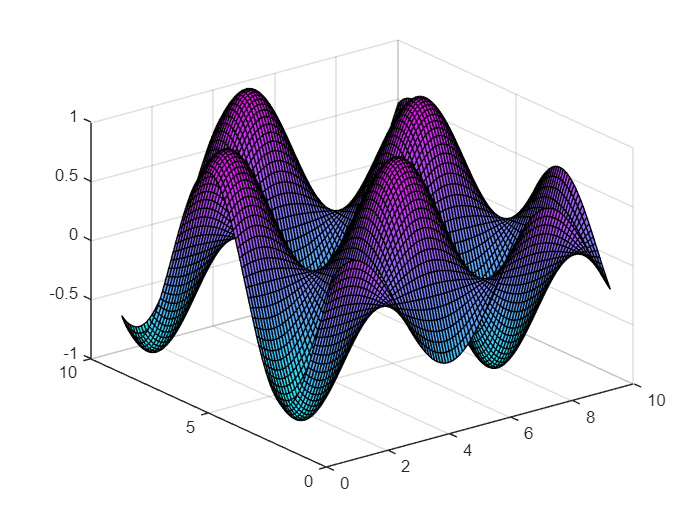

colormap cool

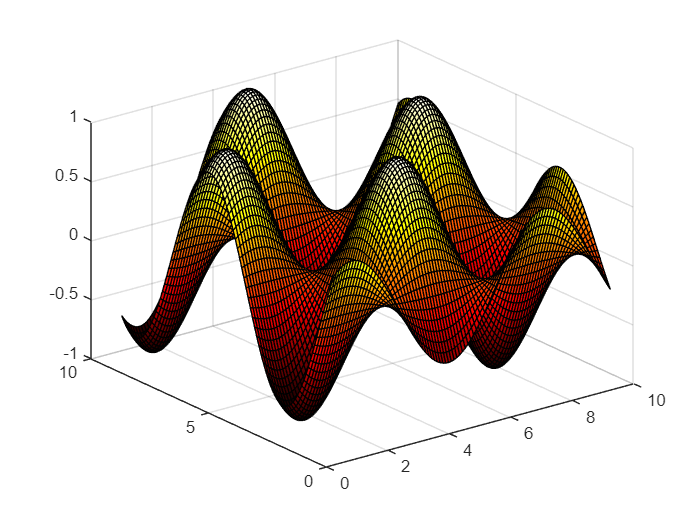

colormap hot

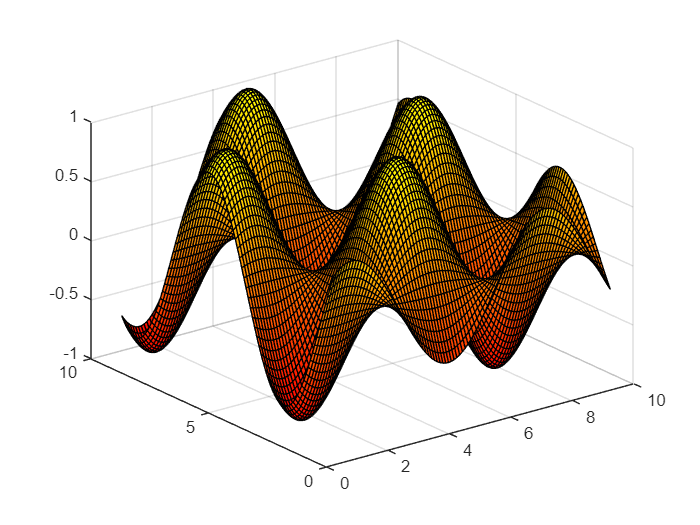

colormap autumn

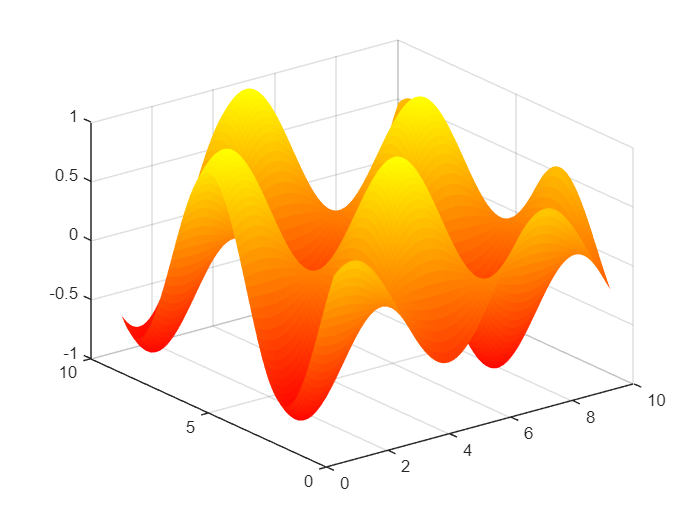

shading flat

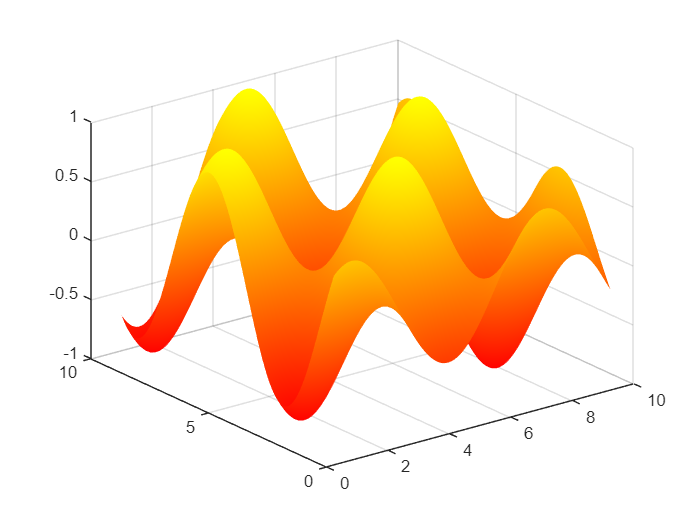

shading interp

shading faceted

### Задание 7

Оформление графиков функций.

X = linspace(0, 2 * pi);
Y = [sin(X); cos(X)]

Y =          0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638    0.9450    0.9224    0.8960    0.8660    0.8326    0.7958    0.7557    0.7127    0.6668    0.6182    0.5671    0.5137    0.4582    0.4009    0.3420    0.2817    0.2203    0.1580    0.0951    0.0317
    1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665   -0.3271   -0.3863   -0.4441   -0.5000   -0.5539   -0.6056   -0.6549   -0.7015   -0.7453   -0.7861   -0.8237   -0.8580   -0.8888   -0.9161   -0.9397   -0.9595   -0.9754   -0.9874   -0.9955   -0

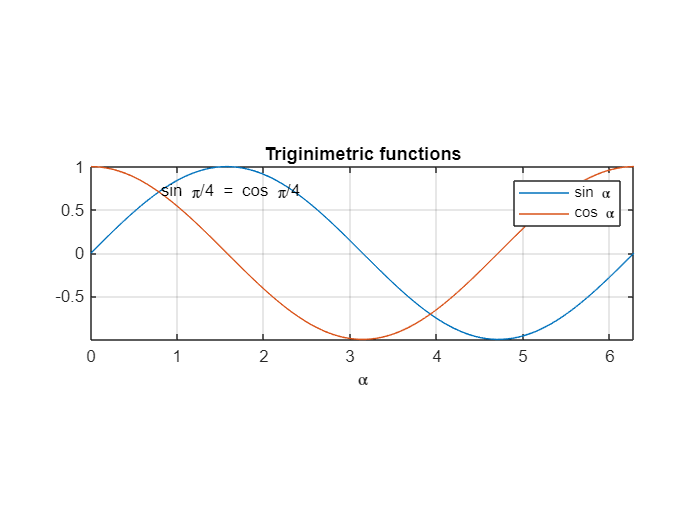

plot(X, Y)
title('Triginimetric functions')
xlabel('\alpha');
text(pi / 4, sin(pi / 4), 'sin \pi/4 = cos \pi/4')
axis equal
% sets the aspect ratio so that the data units are the same in every direction
legend('sin \alpha', 'cos \alpha')
axis tight
% sets the axis limits to the range of the data
grid on

### Задание 9

Контурные графики. Изобразить линии уровня на плоскости xy (функция contour) и подписать для каждой линии уровня соответствующее значение (функция clabel), которое принимает на ней исследуемая функция.

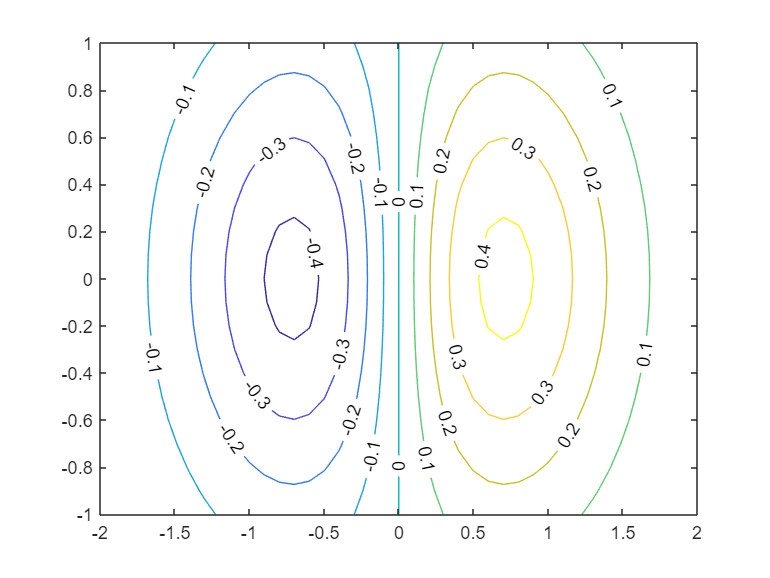

[x, y] = meshgrid(-2:.1:2, -1:.1:1);
z = x.*exp(-x.^2 - y.^2);
[c, h] = contour(x, y, z); % pecifies the x and y coordinates for the values in z
clabel(c, h)

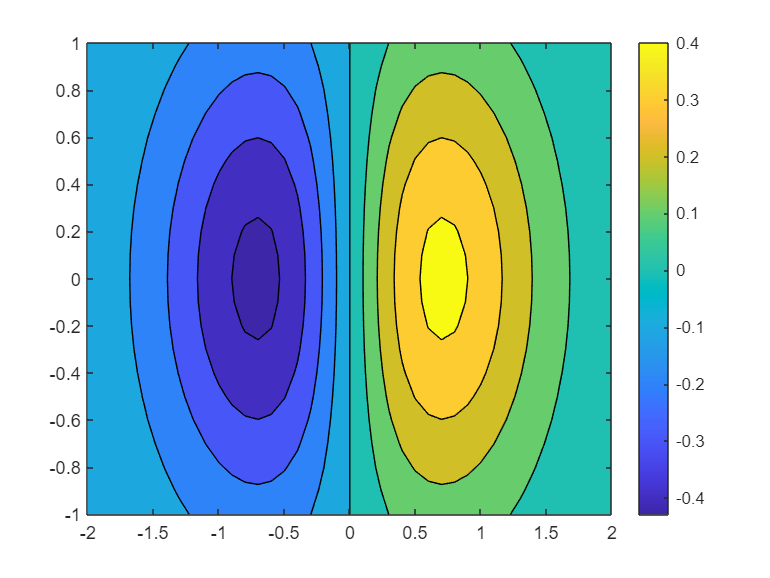

contourf(x, y, z);
colorbar

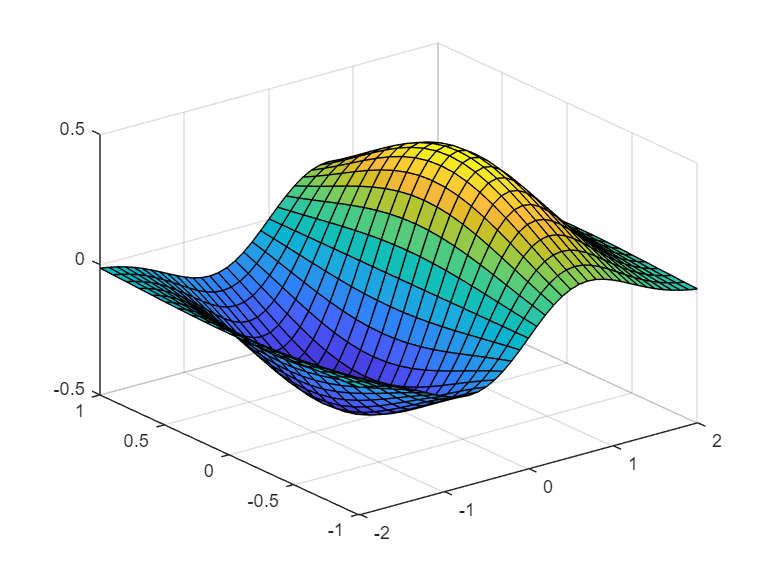

surf(x, y, z)

### Задание 10

Построение графиков в разных системах координат в одном графическом окне. Введите команды.

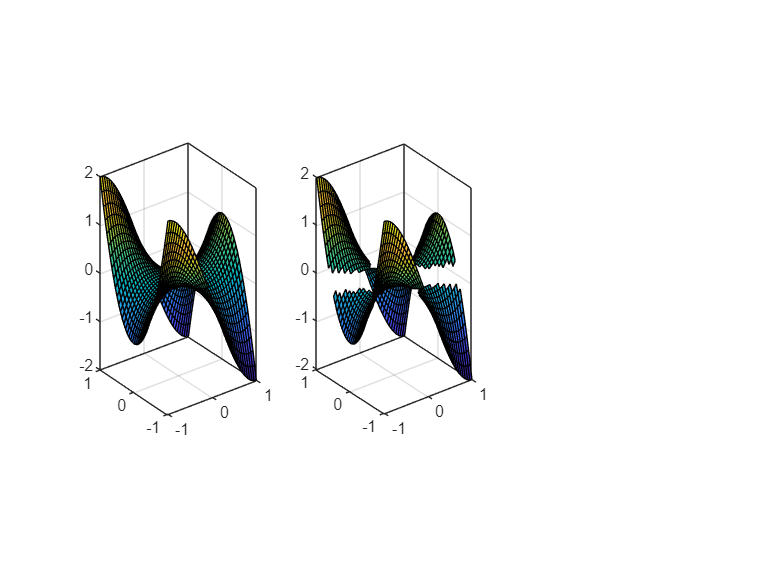

[X, Y] = meshgrid(-1:.05:1);
Z = X .^ 3 - 3 * X .* Y .^ 2;
subplot(1, 3, 1) % divides the current figure into an m-by-n grid and creates axes in the position specified by p
surf(X, Y, Z)
axis equal
axis tight
box on % box on displays the box outline around the current axes by setting their Box property to 'on'. This property value is the default for GeographicAxes objects
ind = abs(Z) < 0.1;
Z(ind) = NaN;
subplot(1, 3, 2)
surf(X, Y, Z)
axis equal
axis tight
box on

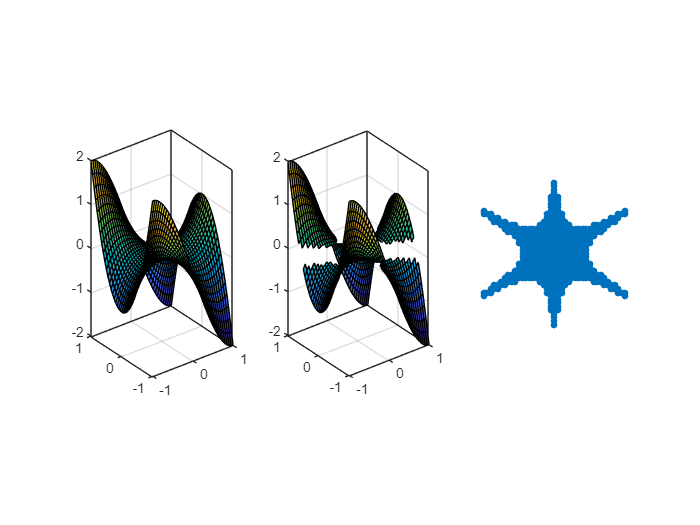

subplot(1, 3, 3)
spy(isnan(Z))
axis equal
axis tight
axis off

### Задание 11

«Томограмма». 3D-графика и анимация. Построить график заданной функции двух переменных и просканировать (снизу вверх) ее горизонтальные уровни. Для этого:

- Разбить графическое окно Figure на две системы координат; 

- в левой системе координат изобразить саму поверхность (3Dповерхность); 

- в правой системе координат нарисовать карту ее произвольного горизонтального сечения (2D-изображение). 

В цикле для любого уровня Z = Z0: 

- из поверхности ВЫРЕЗАТЬ данный уровень; 

- справа изобразить карту данного уровня, то есть местоположение вырезанных ячеек.

a = linspace(1, 10, 100);
plane = zeros(100, 100)

plane =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

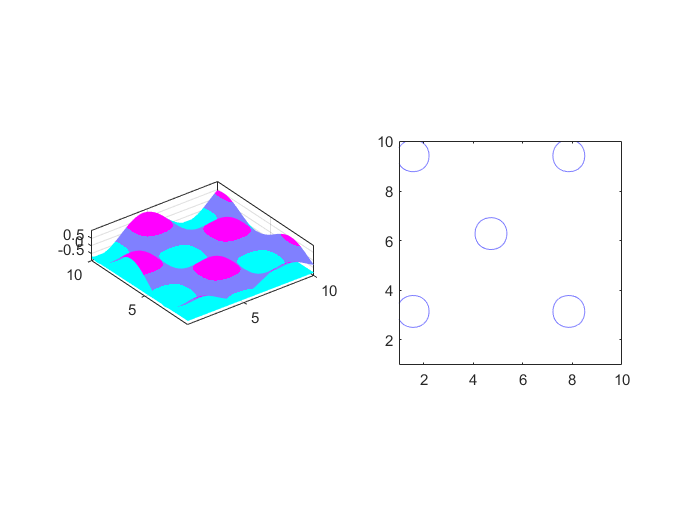

[x y] = meshgrid(a); % возвращает 2D сетку координат, основанную на координатах, содержащихся в векторе a, x - матрица, где каждая строка копия a, y - это матрица,
% где каждый столбец - копия a
my_colors = [0.5, 0.5, 0.5; 0.5, 0.5, 0.5; 0.5, 0.5, 0.5];
for i = -1:0.1:1
    subplot(1, 2, 1)
    plane(:, :) = i;
    surf(x, y, plane)
    hold on
    z = sin(x) .* cos(y);
    surf(x, y, z)
    hold off
    axis equal
    axis tight
    box on
    shading interp
    subplot(1, 2, 2)
    v = [i, i];
    [c, h] = contour(x, y, z, v); % pecifies the x and y coordinates for the values in z
    axis equal
    box on
    drawnow
    % clabel(c, h)
end

% Пример, чтобы не забыть
x = 1:5;
[X,Y] = meshgrid(x)

X =      1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5


Y =      1     1     1     1     1
     2     2     2     2     2
     3     3     3     3     3
     4     4     4     4     4
     5     5     5     5     5


g = ones(3, 3)

g =      1     1     1
     1     1     1
     1     1     1


g(:, :) = 2

g =      2     2     2
     2     2     2
     2     2     2
